# Forward kinematics

Copyright (C) 1993-2017, by Peter I. Corke, http://www.petercorke.com

Forward kinematics is the problem of solving the Cartesian position and orientation of a mechanism given knowledge of the kinematic structure and the joint coordinates.

We will work with a model of the Puma 560 robot

mdl_puma560

which creates some variables in your MATLAB workspace

about p560

p560 [SerialLink] : 1x1 (8 bytes)


about qz

qz [double] : 1x6 (48 bytes)


which is a vector that represents the joint coordinates of zero

qz

qz =      0     0     0     0     0     0


The forward kinematics may be computed using fkine() method of the p560 robot object

T = p560.fkine(qz)

 

T = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.4318
         0         0         0         1


which is a homogeneous transform corresponding to the pose of last link of the  manipulator. This is represented by a Toolbox SE3 object

about T

T [SE3] : 1x1 (128 bytes)


fkine() can also be used with a time sequence of joint coordinates, or trajectory, which is generated by jtraj()

t = [0:.056:2]; 	% generate a time vector
q = jtraj(qz, qr, t); % compute the joint coordinate trajectory

about q

q [double] : 36x6 (1.7 kB)


then the homogeneous transform for each set of joint coordinates is given by

T = p560.fkine(q);
about T

T [SE3] : 1x36 (4.6 kB)


where T is a vector of SE3 objects.

For example, the first pose is

T(1)

 

ans = 
         1         0         0    0.4521
         0         1         0     -0.15
         0         0         1    0.4318
         0         0         0         1


and the tenth pose is

T(10)

 

ans = 
         1         0         0    0.4455
         0         1         0     -0.15
         0         0         1    0.5068
         0         0         0         1


the translational part of this can be extracted using the transl method which is a 36x3 matrix, one row per time step

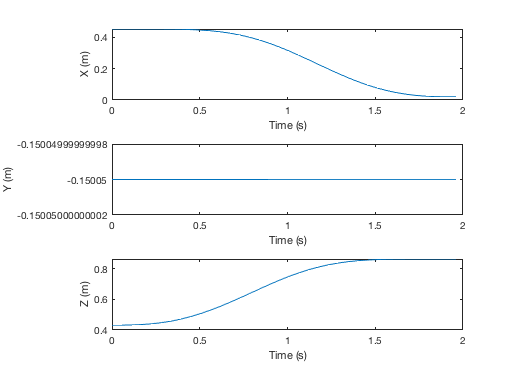

p = T.transl;
subplot(3,1,1); plot(t, p(:,1)); xlabel('Time (s)'); ylabel('X (m)')
subplot(3,1,2); plot(t, p(:,2)); xlabel('Time (s)');ylabel('Y (m)')
subplot(3,1,3); plot(t, p(:,3)); xlabel('Time (s)');ylabel('Z (m)')

or we could plot X against Z to get some idea of the Cartesian path followed by the manipulator.

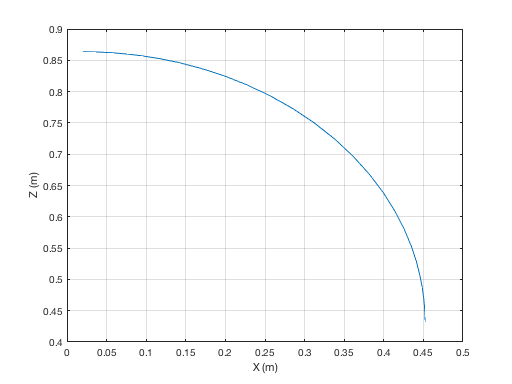

subplot(1,1,1)
plot(p(:,1), p(:,3));
xlabel('X (m)')
ylabel('Z (m)')
grid